House Keeping

clear;clc;close all;

% Physical constants
rho = 1000;
g = 9.8;

% Define the true impedance function
Z_true = @(w) 2 .* w.^3 ./ (rho * g^2);

% Choose two fitting frequencies (Hz)
frequencies_fit = [0.11, 0.18];
omega_fit = 2 * pi * frequencies_fit;

% Build design matrix for Z = A2 * w^2 + A0
W = [omega_fit'.^2, ones(length(omega_fit), 1)];
Zvals = Z_true(omega_fit)';

% Solve for [A2; A0]
coeffs = W \ Zvals;
A2 = coeffs(1);
A0 = coeffs(2);

fprintf('Second-order + constant approximation coefficients:\n');

Second-order + constant approximation coefficients:


fprintf('A2 = %.4e\nA0 = %.4e\n', A2, A0);

A2 = 2.9012e-05
A0 = -6.9831e-06


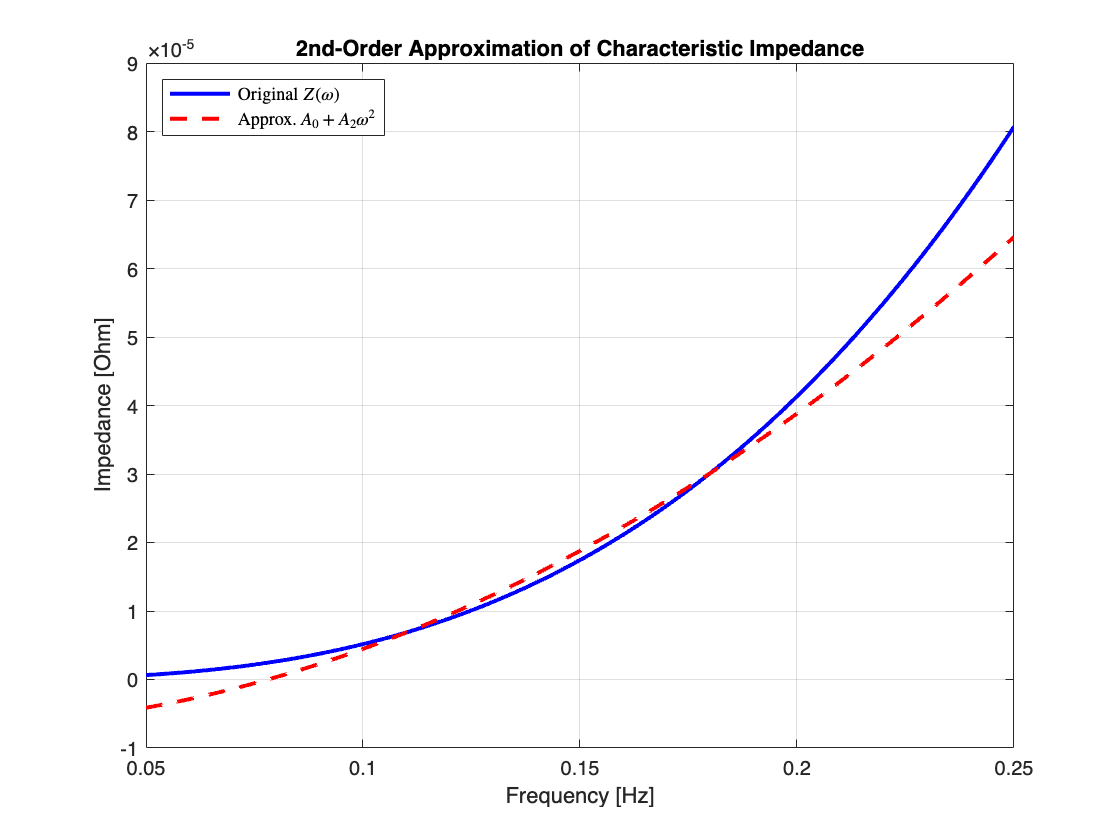


% Frequency range for evaluation
f = linspace(0.05, 0.25, 1000);
omega_plot = 2 * pi * f;
Z_orig = Z_true(omega_plot);

% Approximate impedance
Z_approx = A2 * omega_plot.^2 + A0;

% Plot results
figure;
plot(f, Z_orig, 'b-', 'LineWidth', 2); hold on;
plot(f, Z_approx, 'r--', 'LineWidth', 2);
xlabel('Frequency [Hz]');
ylabel('Impedance [Ohm]');
title('2nd-Order Approximation of Characteristic Impedance');
legend('Original $Z(\omega)$', ...
       'Approx. $A_0 + A_2 \omega^2$', ...
       'Interpreter', 'latex', 'Location', 'northwest');
grid on;

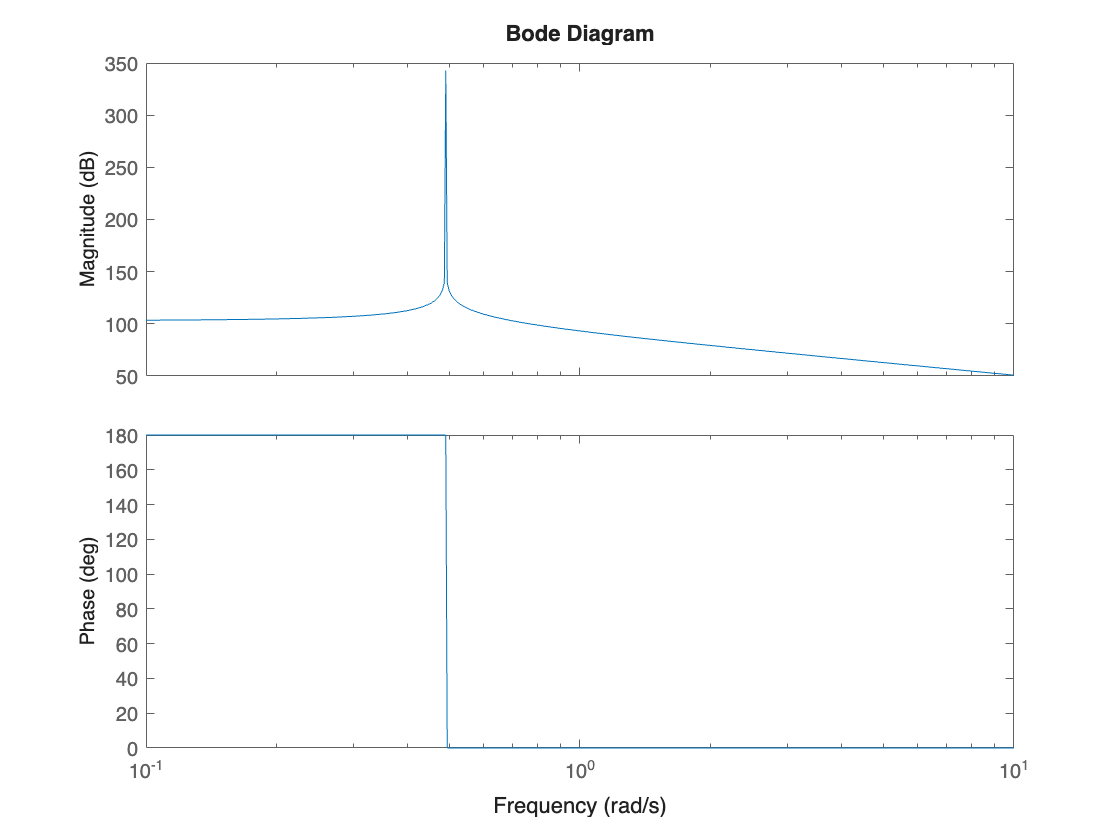


% Frequency range for comparison
f = linspace(0.05, 0.25, 1000);
omega_plot = 2 * pi * f;
Z_orig = Z_true(omega_plot);

% Evaluate approximation (no A2 term)
Z_approx = A2 * omega_plot.^2 + A0;

% Plot comparison
figure;
plot(f, Z_orig, 'b-', 'LineWidth', 2); hold on;
plot(f, Z_approx, 'r--', 'LineWidth', 2);
xlabel('Frequency [Hz]');
ylabel('Impedance [Ohm]');
title('Impedance Approximation without $\omega^2$ Term');
grid on;
Den = [-A2 0 A0];
sys=tf(1,Den);
poles=pole(sys);

bodeplot(sys)

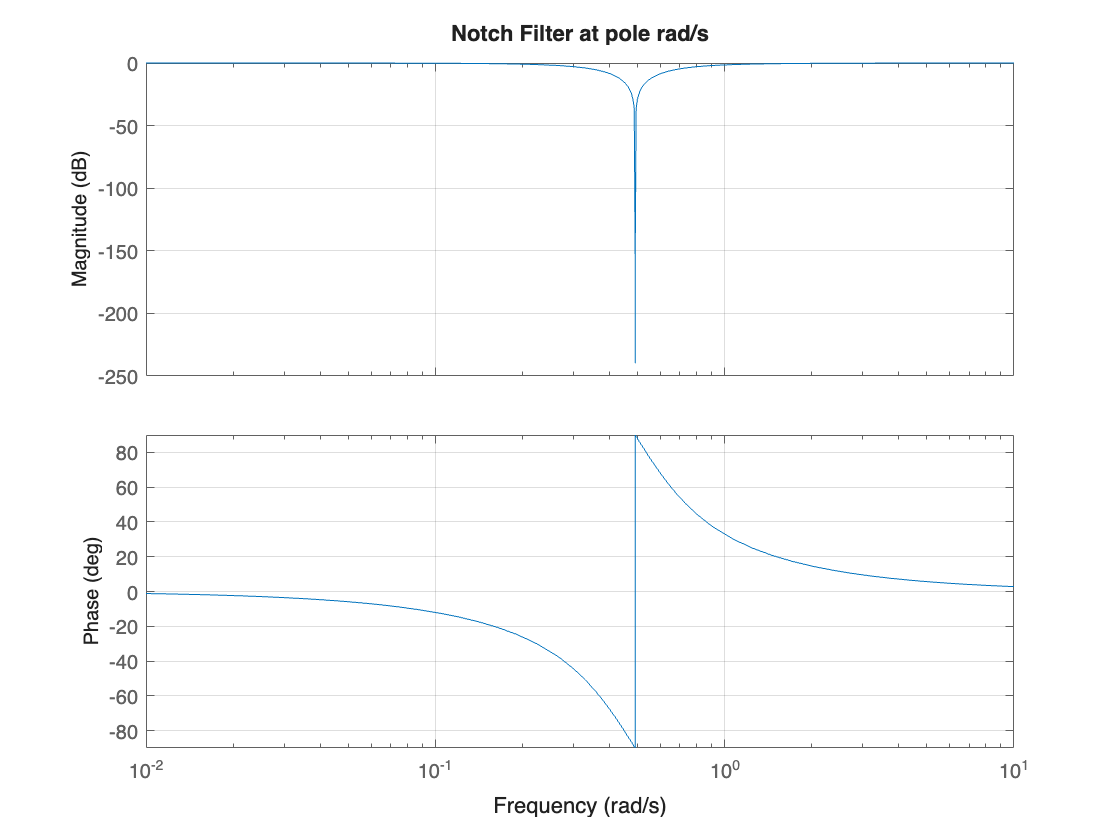



% Define notch filter parameters
omega_notch = abs(imag(poles(2)));    % rad/s
zeta = 0.5;            % narrow notch

% Numerator and denominator
Num = [1 0 omega_notch^2];
Den = [1 2*zeta*omega_notch omega_notch^2];

% Define the notch filter transfer function
notch_filter = tf(Num, Den);

% Plot notch filter Bode plot
figure
bodeplot(notch_filter);
title('Notch Filter at pole rad/s');
grid on;

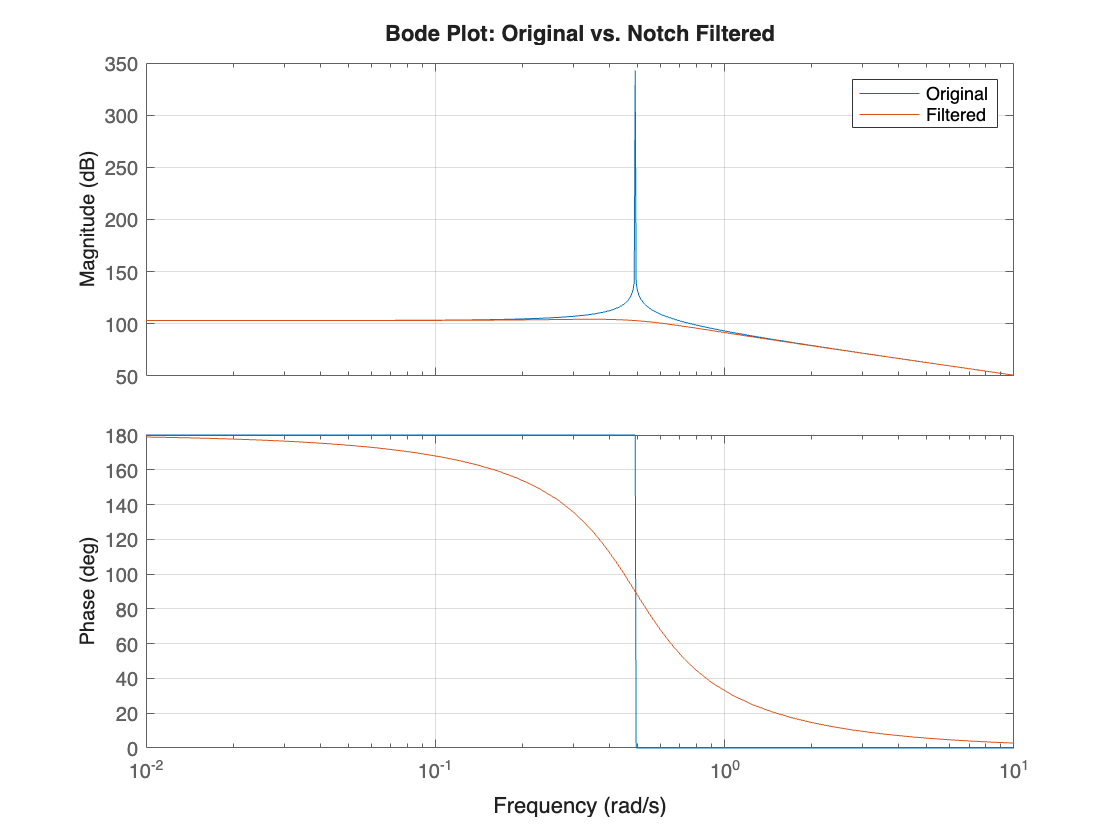


% Apply filter to the system
filtered_sys = notch_filter * sys;
Num=cell2mat(filtered_sys.Numerator);
Den=cell2mat(filtered_sys.Denominator);
% Bode plot comparison
figure
bodeplot(sys, filtered_sys);
legend("Original", "Filtered");
title('Bode Plot: Original vs. Notch Filtered');
grid on;

% 
% %sat_lim = 2*pi*0.05; % frequency saturation limit at 20s period of wave
% epsilon =    Z_true(sat_lim)
% R = 0.0001;  % Small damping
% Den = [A4 R -A2 0 epsilon];
% sys = tf(1, Den);
% 
% tf_SIL = tf(1,Den);
% bodeplot(tf_SIL)
% 
% % === Coefficient checks ===
% disp('--- Coefficient Check ---');
% disp(['A2 = ', num2str(A2)]);
% disp(['A4 = ', num2str(A4)]);
% 
% if A4 <= 0
%     warning('A4 should be positive for a stable high-frequency response.');
% end
% if A0 <= 0
%     warning('A2 should be positive for a stable mid-frequency response.');
% end
% 
% 
% % === Causality and Properness ===
% disp('--- Causality & Properness Check ---');
% % [numDeg, denDeg] = order(sys);
% % disp(['Numerator degree: ', num2str(numDeg)]);
% % disp(['Denominator degree: ', num2str(denDeg)]);
% % if denDeg < numDeg
% %     warning('System is non-causal or improperly defined (den < num)');
% % else
% %     disp('✅ System is proper (causal structure ok).');
% % end
% 
% % === Pole stability check ===
% disp('--- Pole Stability Check ---');
% poles = pole(sys);
% disp(poles);
% 
% if any(real(poles) > 0)
%     warning('❌ System is unstable (pole in right-half plane)');
% elseif any(real(poles) == 0)
%     warning('⚠️ System is marginally stable (pole on imaginary axis)');
% else
%     disp('✅ All poles in LHP: system is stable');
% end
% 
% % === Epsilon check (low-freq limit) ===
% disp('--- Epsilon Check ---');
% disp(['Epsilon (Z at 0.05 Hz) = ', num2str(epsilon)]);
% if epsilon < 1e-6
%     warning('Epsilon is too small — may still lead to instability at low frequency');
% else
%     disp('✅ Epsilon provides sufficient low-frequency floor');
% end
% figure;
% pzmap(sys);
% title('Pole-Zero Map of H(s) = 1/Z(s)');
% grid on;
% 